# Figure 3 on events (with associated supplemental figures)

## PLS plots

d = SessManager.load_special('Mouse2022');
alpha = 0.02;

[X, ks] = d.get_dataset;
X_shuf = shuffle(X, ks);
X_z = zscore(X);
X_shuf_z = zscore(X_shuf);
[XS, stats, origin] =...
    Utils.pls_short(X_z, [ceil(ks/2), mod(ks,2)]);
XS_s = (X_shuf_z - mean(X_shuf_z)) * stats.W;
origin_s = -mean(X_shuf_z) * stats.W;

Using one session from Mouse2022, showing real data:

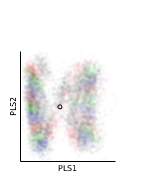

figure;
scatter(XS(:,1), XS(:,2), 8,...
    Utils.colorcode(ceil(ks/2)),...
    'filled', 'MarkerFaceAlpha', alpha);
hold on;
scatter(origin(1), origin(2), 10, 'k');
xlabel PLS1
ylabel PLS2
axis equal; 
axis tight;
xl_ = xlim;
yl_ = ylim;
set(gca, 'XTick', []);
set(gca, 'YTick', []);
figure_format('boxsize', [1 1.2], 'fontsize', 6);
Utils.printto('events_figs/f3_events', 'PLS_events_real.pdf');

And shuffled data:

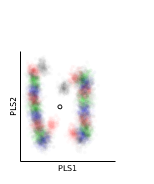

figure;
scatter(XS_s(:,1), XS_s(:,2), 8,...
    Utils.colorcode(ceil(ks/2)),...
    'filled', 'MarkerFaceAlpha', alpha);
hold on;
scatter(origin_s(1), origin_s(2), 10, 'k');
xlabel PLS1;
ylabel PLS2;
axis equal;
axis tight;
xlim(xl_);
ylim(yl_);
set(gca, 'XTick', []);
set(gca, 'YTick', []);
figure_format('boxsize', [1 1.2], 'fontsize', 6);
Utils.printto('events_figs/f3_events', 'PLS_events_shuf.pdf');

## Signal and noise

s_inds = SessManager.special_sessions_usable_index({'Mouse2022', 'Mouse2024', 'Mouse2028'});
get_usable_result = @(idx) load(onefile(['records_adjacent_metrics_events_transients/*_' num2str(idx, '%.3d') '_*']));

res = cell(1,numel(s_inds));
for s_ix = 1:numel(s_inds)
    res{s_ix} = get_usable_result(s_inds(s_ix));
end

cutoff = 100;
asymp_line = @(n,m) Utils.fitaline(n,m,cutoff);
res_lookup = @(res, code)...
    cellfun(@(x)...
    cellfun(@(y)...
    median(y{code(1),code(2:3)}),...
    x.results_table),...
    res,'UniformOutput',false);


n = cellfun(@(x)x.n_sizes, res, 'UniformOutput', false);
signal = res_lookup(res, 'mse');
noise = res_lookup(res, 'mce');
noise_shuf = res_lookup(res, 'mue');

snr = cellfun(@rdivide, signal, noise,...
    'UniformOutput', false);
snr_shuf = cellfun(@rdivide, signal, noise_shuf,...
    'UniformOutput', false);

[signal_slope, signal_slope_conf] = cellfun(asymp_line, n, signal,...
    'UniformOutput', false);
[noise_slope, noise_slope_conf] = cellfun(asymp_line, n, noise,...
    'UniformOutput', false);
[noise_shuf_slope, noise_shuf_slope_conf] = cellfun(asymp_line, n, noise_shuf,...
    'UniformOutput', false);

[asymp_snr, asymp_snr_conf] = cellfun(@uncertain_divide, signal_slope, signal_slope_conf,...
    noise_slope, noise_slope_conf);
[asymp_snr_shuf, asymp_snr_shuf_conf] = cellfun(@uncertain_divide, signal_slope, signal_slope_conf,...
    noise_shuf_slope, noise_shuf_slope_conf);

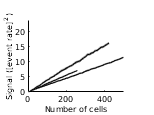

dff2_lim = [0 24];
figure;
MultiSessionVisualizer.plot_single_filtered(n, {signal}, {'k'}, [true true true]);
ylim(dff2_lim);
xlabel 'Number of cells'
ylabel 'Signal ([event rate]^2)'
figure_format([1 0.75]);
Utils.printto('events_figs/f3_events', 'signal_events.pdf');

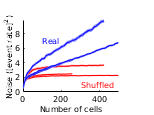


figure;
MultiSessionVisualizer.plot_single_filtered(n, {noise_shuf, noise}, {'r', 'b'}, [true true true]);

text(100, 7, 'Real', 'Color', 'b');
text(300, 1, 'Shuffled', 'Color', 'r');
xlabel 'Number of cells'
ylabel 'Noise ([event rate]^2)'
figure_format([1 0.75]);
Utils.printto('events_figs/f3_events', 'noise_events.pdf');

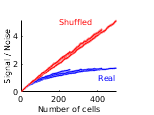


figure;
MultiSessionVisualizer.plot_single_filtered(n, {snr, snr_shuf}, {'b', 'r'}, [true true true]);
text(200, 5, 'Shuffled', 'Color', 'r');
text(400, 1, 'Real', 'Color', 'b');
xlabel 'Number of cells'
ylabel 'Signal / Noise'
figure_format([1 0.75]);
Utils.printto('events_figs/f3_events', 'snr_events.pdf');

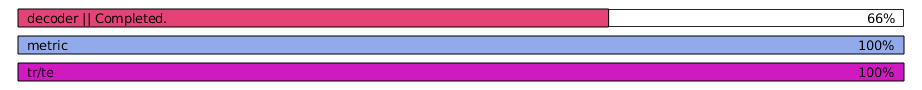

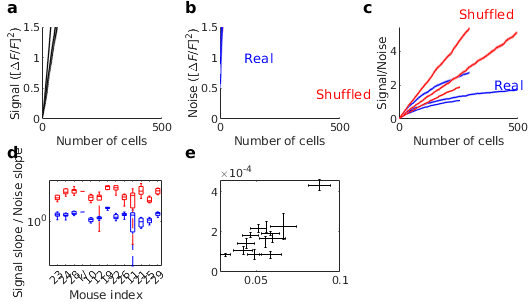

Unable to perform assignment with 0 elements on the right-hand side.

Error in Utils.colorscheme (line 795)
                cs = cs{i};

Error in Utils.names_to_colors (line 809)
                c(i,:) = Utils.colorscheme(index);

Error in DecodeTensor.mcolor (

signal_and_noise_analysis

org = Org;
org.init;

fname_save = 'eigen_snr_crossval_save.mat';
if ~exist(fname_save, 'file')
    NU = sm.num_usable;
    WaitMessage = parfor_wait(NU);
    [dp2_train, dp2_test, signal_train, signal_test, noise_train, noise_test] = deal(cell(1,NU));
    parfor i = 1:NU
        cloud = Cloud(i);
        [dp2_train{i}, dp2_test{i},...
            signal_train{i}, signal_test{i},...
            noise_train{i}, noise_test{i}] = cloud.eigen_snr_crossval;
        WaitMessage.Send;
    end
    WaitMessage.Destroy;
    save eigen_snr_crossval_save.mat dp2_train dp2_test signal_train signal_test noise_train noise_test
end

p = Pub(14, 8, 'rows', 2, 'columns', 3, 'start_char', 'f');

%3f
p.panel(1,...
    'xlab', 'Mouse name (Mouse20XX)',...
    'ylab', 'Asymptotic SNR');
org.boxplot('asymp_snr', 'asymp_snr_shuf', true, false);


%3g
p.panel(2,...
    'xlab', 'Single-cell SNR',...
    'ylab', '{\itI}_0 fit value (cm^{-2}\cdotneurons^{-1})');
org.correlogram('single_dp2', 'I0', true, true);

Using only 73 out of 110 sessions
Mouse-aggregated correlations single_dp2 vs. I0: adj. R^2 = 0.730
Pearson: 0.872, p = 1.011597e-03, **
Spearman: 0.564, p = 9.579157e-02, n.s
Kendall: 0.467, p = 7.255015e-02, n.s


p.format;
Utils.fix_exponent(gca, 'y', 1);

%3h
p.panel(3,...
    'xlab', 'Asymptotic SNR',...
    'ylab', sprintf('Asymptotic fit IMSE (cm^{-2})'));
org.correlogram('asymp_snr', 'I0N', true, true);

Using only 73 out of 110 sessions
Mouse-aggregated correlations asymp_snr vs. I0N: adj. R^2 = 0.876
Pearson: 0.943, p = 4.193936e-05, ***
Spearman: 0.891, p = 1.380267e-03, **
Kendall: 0.778, p = 9.463183e-04, ***



%3i
p.panel(4,...
    'xlab', 'PC index',...
    'ylab', 'Eigenmode SNR');
org.eigen_snr_crossval_aggregation(true);

Sum of dp2 from 1 to 6 (the max) = 0.332688
 which is 8.381813% of the total 3.969170


ylim([0 0.11]);

MAX_DIM = 6;
%3j
p.panel(5,...
    'xlab', 'PC index',...
    'ylab', 'cos^2(PC_i, \Delta\mu)');
org.area_between_cos2(MAX_DIM);

%3k
p.panel(6,...
    'xlab', sprintf('Area between PC_{[1-%d]}', MAX_DIM),...
    'ylab', '1/{\itN} fit value (neurons^{-1})');
name = sprintf('delta_cos2_area_%d', MAX_DIM);
org.correlogram(name, 'invN50', true, true, true);

Using only 70 out of 110 sessions
Mouse-aggregated correlations delta_cos2_area_6 vs. invN50: adj. R^2 = 0.048
Pearson: 0.392, p = 2.628406e-01, n.s
Spearman: 0.636, p = 5.444507e-02, n.s
Kendall: 0.511, p = 4.662257e-02, *


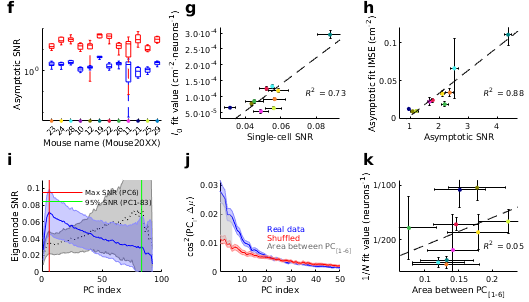

Nvals = [200 100 65 50];
Nlabels = arrayfun(@(x)['1/' num2str(x)],Nvals,'UniformOutput',false);
set(gca, 'YTick', 1./Nvals);
set(gca, 'YTickLabels', Nlabels);

p.format;
p.print('events_figs/f3_events', 'f3_second_half', true);

%savefig('f3_update');

p = Pub(14, 8, 'rows', 2, 'columns', 3, 'start_char', 'f');


%3f
p.panel(1,...
    'xlab', 'Mouse name (Mouse20XX)',...
    'ylab', 'Asymptotic SNR');
org.boxplot('asymp_snr', 'asymp_snr_shuf', true, false);


%3g
p.panel(2,...
    'xlab', 'Single-cell SNR',...
    'ylab', '{\itI}_0 fit value (cm^{-2}\cdotneurons^{-1})');
org.correlogram('single_dp2', 'I0', true, true);

Using only 73 out of 110 sessions
Mouse-aggregated correlations single_dp2 vs. I0: adj. R^2 = 0.730
Pearson: 0.872, p = 1.011597e-03, **
Spearman: 0.564, p = 9.579157e-02, n.s
Kendall: 0.467, p = 7.255015e-02, n.s


p.format;
Utils.fix_exponent(gca, 'y', 1);

%3h
p.panel(3,...
    'xlab', 'Asymptotic SNR',...
    'ylab', sprintf('Asymptotic fit IMSE (cm^{-2})'));
org.correlogram('asymp_snr', 'I0N', true, true);

Using only 73 out of 110 sessions
Mouse-aggregated correlations asymp_snr vs. I0N: adj. R^2 = 0.876
Pearson: 0.943, p = 4.193936e-05, ***
Spearman: 0.891, p = 1.380267e-03, **
Kendall: 0.778, p = 9.463183e-04, ***



%3i
p.panel(4,...
    'xlab', 'PC index',...
    'ylab', 'Eigenmode SNR');
org.eigen_snr_crossval_aggregation(true);

Sum of dp2 from 1 to 6 (the max) = 0.332688
 which is 8.381813% of the total 3.969170


ylim([0 0.11]);


%3j
p.panel(5,...
    'xlab', 'corr. PC index',...
    'ylab', 'cos^2(corr. PC_i, \Delta\mu)');
%org.area_between_cos2(24);
MAX_DIM = 50;
[cl2, cl2_sem] = org.all_med_bins('corr_loadings2', 'restrict');
[cl2_s, cl2_s_sem] = org.all_med_bins('corr_loadings_shuf2', 'restrict');
%[cl2, cl2_sem] = org.all_med_bins('loadings2', 'restrict');
%[cl2_s, cl2_s_sem] = org.all_med_bins('loadings_shuf2', 'restrict');
serrorbar(cl2, cl2_sem*1.96, 'b');
hold on;
serrorbar(cl2_s, cl2_s_sem*1.96, 'r');
patch([1:MAX_DIM, MAX_DIM:-1:1],...
    [cl2(1:MAX_DIM)', cl2_s(MAX_DIM:-1:1)'],...
    [1 1 1]*0.8, 'FaceAlpha', 0.6, 'EdgeColor', 'none');
ylim([0 Inf]);
%xlim([1 50]);
xlim([1 Inf]);
xlabel 'corr. PC index'
ylabel 'cos^2(PC_i, \Delta\mu)'
text(20,0.045/3,'Real data', 'Color', 'b');
text(20,0.035/3,'Shuffled', 'Color', 'r');
text(20, 0.025/3,...
    'Area between all PCs', 'Color', [1 1 1]*0.4);

%3k
MAX_DIM = 83;
p.panel(6,...
    'xlab', 'Area between all PCs',...
    'ylab', '1/{\itN} fit value (neurons^{-1})');
%name = sprintf('corr_delta_cos2_area_%d', MAX_DIM);
%org.correlogram(name, 'invN50', true, true, true);
org.correlogram('corr_cos2_area', 'invN50', true, true, true);

Using only 70 out of 110 sessions
Mouse-aggregated correlations corr_cos2_area vs. invN50: adj. R^2 = 0.575
Pearson: 0.789, p = 6.697114e-03, **
Spearman: 0.770, p = 1.367178e-02, *
Kendall: 0.600, p = 1.666612e-02, *


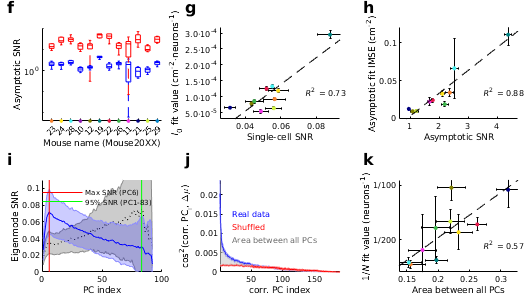

%org.correlogram('cos2_area', 'invN50', true, true, true);
Nvals = [200 100 65 50];
Nlabels = arrayfun(@(x)['1/' num2str(x)],Nvals,'UniformOutput',false);
set(gca, 'YTick', 1./Nvals);
set(gca, 'YTickLabels', Nlabels);

p.format;
p.print('events_figs/f3_events', 'f3_second_half_alt', true);

%savefig('f3_update');

## Figure 4 stuff (move to separate file later)

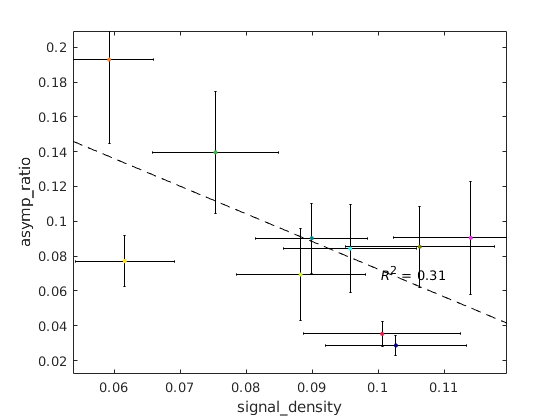

Special for asymp_ratio, removing outliers > 7
Using only 72 out of 110 sessions
Mouse-aggregated correlations signal_density vs. asymp_ratio: adj. R^2 = 0.308
Pearson: -0.620, p = 5.568617e-02, n.s
Spearman: -0.297, p = 4.069502e-01, n.s
Kendall: -0.244, p = 3.807198e-01, n.s


figure;
org.correlogram('signal_density', 'asymp_ratio', true, true, true);

figure;

org.correlogram('dmu_ipr', 'inv_asymp_ratio', true, true, true);

Using only 72 out of 110 sessions
Mouse-aggregated correlations dmu_ipr vs. inv_asymp_ratio: adj. R^2 = 0.836
Pearson: 0.924, p = 1.324509e-04, ***
Spearman: 0.758, p = 1.592083e-02, *
Kendall: 0.556, p = 2.860946e-02, *


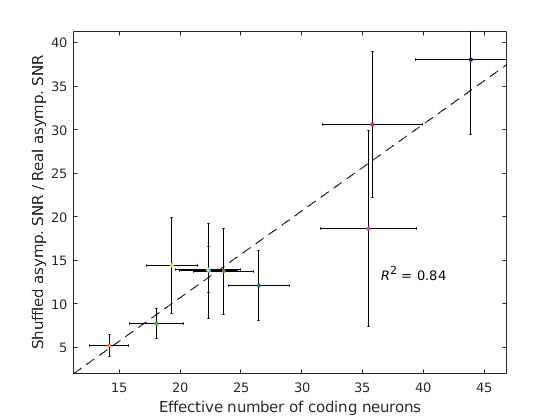

xlabel 'Effective number of coding neurons'
ylabel 'Shuffled asymp. SNR / Real asymp. SNR'

Passes a path analysis with number of neurons:

fitlm([zscore(org.sess_prop.num_neurons), zscore(org.sess_prop.dmu_ipr)], zscore(org.sess_prop.inv_asymp_ratio))

ans = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                    Estimate        SE         tStat         pValue  
                   __________    ________    __________    __________

    (Intercept)    4.2968e-16     0.05739    7.4871e-15             1
    x1               -0.10025    0.072991       -1.3734        0.1725
    x2                0.86028    0.072991        11.786    4.7052e-21


Number of observations: 110, Error degrees of freedom: 107
Root Mean Squared Error: 0.602
R-squared: 0.644,  Adjusted R-Squared: 0.638
F-statistic vs. constant model: 96.9, p-value = 9.55e-25

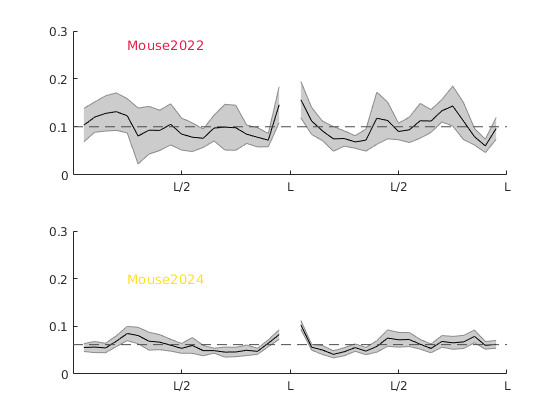

figure;

subplot(2,1,1);
mouse_name = 'Mouse2022';
[m,s]=org.mouse_by_bins('signal_density', {mouse_name, 'restrict'});
mean_sig_dens = nanmean(m);
serrorbar(1:20, m(1:20),s(1:20)*1.96);
hold on;
serrorbar(21:40, m(21:40),s(21:40)*1.96);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
ylim([0 0.3]);
ax=gca;
ax.XTick=10:10:40;
ax.XTickLabel={'L/2','L','L/2','L'};
m_color = DecodeTensor.mcolor({mouse_name});
m_color = m_color{1};
text(5, 0.27, mouse_name, 'Color', m_color);

subplot(2,1,2);
mouse_name = 'Mouse2024';
[m,s]=org.mouse_by_bins('signal_density', {mouse_name, 'restrict'});
mean_sig_dens = nanmean(m);
serrorbar(1:20, m(1:20),s(1:20)*1.96);
hold on;
serrorbar(21:40, m(21:40),s(21:40)*1.96);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
ylim([0 0.3]);
ax=gca;
ax.XTick=10:10:40;
ax.XTickLabel={'L/2','L','L/2','L'};
m_color = DecodeTensor.mcolor({mouse_name});
m_color = m_color{1};
text(5, 0.2, mouse_name, 'Color', m_color);

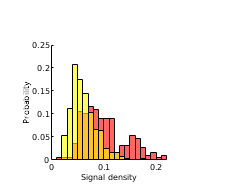


%%
figure;
x_ = org.mouse_all_sess('signal_density', {'Mouse2022', 'restrict'});
x_ = x_(:);
x_(isnan(x_)) = [];

y_ = org.mouse_all_sess('signal_density', {'Mouse2024', 'restrict'});
y_ = y_(:);
y_(isnan(y_)) = [];

bin_width = 0.01;
histogram(x_, 'BinWidth', bin_width, 'FaceColor', 'r', 'Normalization', 'probability');
hold on;
histogram(y_, 'BinWidth', bin_width, 'FaceColor', 'y', 'Normalization', 'probability');
xlabel 'Signal density'
ylabel 'Probability'
%legend 'Mouse2022' 'Mouse2024'

% m_color = DecodeTensor.mcolor({'Mouse2022'});
% m_color = m_color{1};
% text(0.2, 0.23, 'Mouse2022', 'Color', m_color);
% m_color = DecodeTensor.mcolor({'Mouse2024'});
% m_color = m_color{1};
% text(0.2, 0.18, 'Mouse2024', 'Color', m_color);

axis square
figure_format([4 3]/2.5);

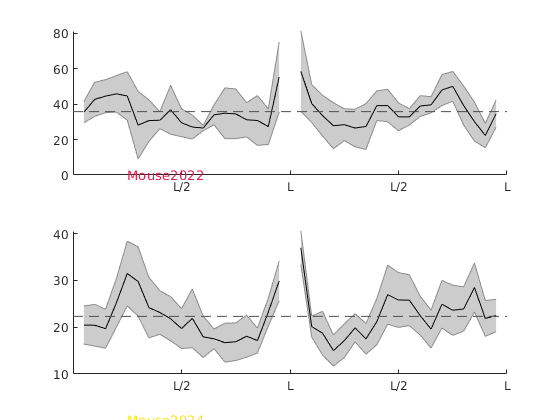

figure;

subplot(2,1,1);
mouse_name = 'Mouse2022';
[m,s]=org.mouse_by_bins('dmu_ipr', {mouse_name, 'restrict'});
mean_sig_dens = nanmean(m);
serrorbar(1:20, m(1:20),s(1:20)*1.96);
hold on;
serrorbar(21:40, m(21:40),s(21:40)*1.96);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
%ylim([0 0.3]);
ax=gca;
ax.XTick=10:10:40;
ax.XTickLabel={'L/2','L','L/2','L'};
m_color = DecodeTensor.mcolor({mouse_name});
m_color = m_color{1};
text(5, 0.27, mouse_name, 'Color', m_color);

subplot(2,1,2);
mouse_name = 'Mouse2024';
[m,s]=org.mouse_by_bins('dmu_ipr', {mouse_name, 'restrict'});
mean_sig_dens = nanmean(m);
serrorbar(1:20, m(1:20),s(1:20)*1.96);
hold on;
serrorbar(21:40, m(21:40),s(21:40)*1.96);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
%ylim([0 0.3]);
ax=gca;
ax.XTick=10:10:40;
ax.XTickLabel={'L/2','L','L/2','L'};
m_color = DecodeTensor.mcolor({mouse_name});
m_color = m_color{1};
text(5, 0.2, mouse_name, 'Color', m_color);

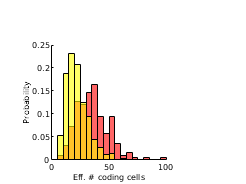


%%
figure;
x_ = org.mouse_all_sess('dmu_ipr', {'Mouse2022', 'restrict'});
x_ = x_(:);
x_(isnan(x_)) = [];

y_ = org.mouse_all_sess('dmu_ipr', {'Mouse2024', 'restrict'});
y_ = y_(:);
y_(isnan(y_)) = [];

bin_width = 5;
histogram(x_, 'BinWidth', bin_width, 'FaceColor', 'r', 'Normalization', 'probability');
hold on;
histogram(y_, 'BinWidth', bin_width, 'FaceColor', 'y', 'Normalization', 'probability');
xlabel 'Eff. # coding cells'
ylabel 'Probability'
%legend 'Mouse2022' 'Mouse2024'

% m_color = DecodeTensor.mcolor({'Mouse2022'});
% m_color = m_color{1};
% text(0.2, 0.23, 'Mouse2022', 'Color', m_color);
% m_color = DecodeTensor.mcolor({'Mouse2024'});
% m_color = m_color{1};
% text(0.2, 0.18, 'Mouse2024', 'Color', m_color);

axis square
figure_format([4 3]/2.5);

function [quotient, quotient_uncertainty] = uncertain_divide(x, xc, y, yc)
quotient = x./y;
quotient_uncertainty = abs(x./y)*sqrt((xc./x).^2 + (yc./y).^2);
end